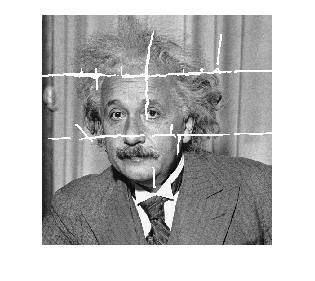

I=imread("EINSTEIN.tif");
g=im2gray(I);
[r c]=size(g);
t=[];

for i=1:1:r

    for j=1:1:c

        if g(i,j)==255
                 
          t(i,j)=0;

        else

           t(i,j)=255;

        end    

    end

end

bin_img=uint8(t);

imshow(I)

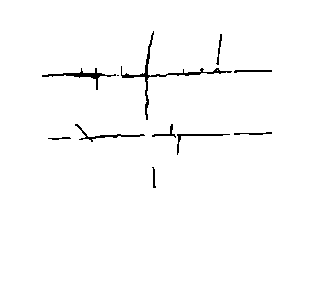


imshow(bin_img)

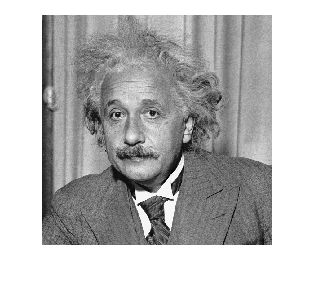


for i=1:1:r
    if g(i,1)==255
        g(i,1)=g(i-1,1);
    end
    if g(i,c)==255
        g(i,c)=g(i-1,c);
    end
end

for j=1:1:r
    if g(1,j)==255
        g(1,j)=g(1,j-1);
    end
    if g(r,j)==255
        g(r,j)=g(r,j-1);
    end
end

for i=1:1:r
    for j=1:1:c
        if g(i,j)==255
            p=i;
            q=j;
            q1=j;
            c1=0;
            c2=0;
            while g(p,q+1)==255
                q=q+1;
                c1=c1 + 1;
            end 
            while g(p+1,q1)==255
                p=p+1;
                c2=c2 + 1;
            end
            if c1 > c2
                m=p-i+1;
                for c3=0:1:(m-1)
                    g(i+c3,j)=(1-(1+c3)/m)*g(i-1,j) + ((1+c3)/m)*g(p+1,j);
                end
            end
            if c1==c2
                   n=q-j+1;
                for c4=0:1:(n-1)
                    g(i,j+c4)=(1-c4/n)*g(i,j-1) + (c4/n)*g(i,q+1);
                end
            end
            if c1 < c2
                n=q-j+1;
                for c4=0:1:(n-1)
                    g(i,j+c4)=(1-(1+c4)/n)*g(i,j-1) + ((1+c4)/n)*g(i,q+1);
                end
            
            end
        end
    end
end


imshow(g)



score1= brisque(g) 

score1 = 28.8809

score2= niqe(g)

score2 = 5.3589

score3= piqe(g) 

score3 = 42.0395